H = tf(2, conv([1 1], [1 1]));
[y,t] = step(H, 30);

info = stepinfo(y, t)

info = struct with fields:
         RiseTime: 3.3681
    TransientTime: 5.8432
     SettlingTime: 5.8432
      SettlingMin: 1.8016
      SettlingMax: 2.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 2.0000
         PeakTime: 30


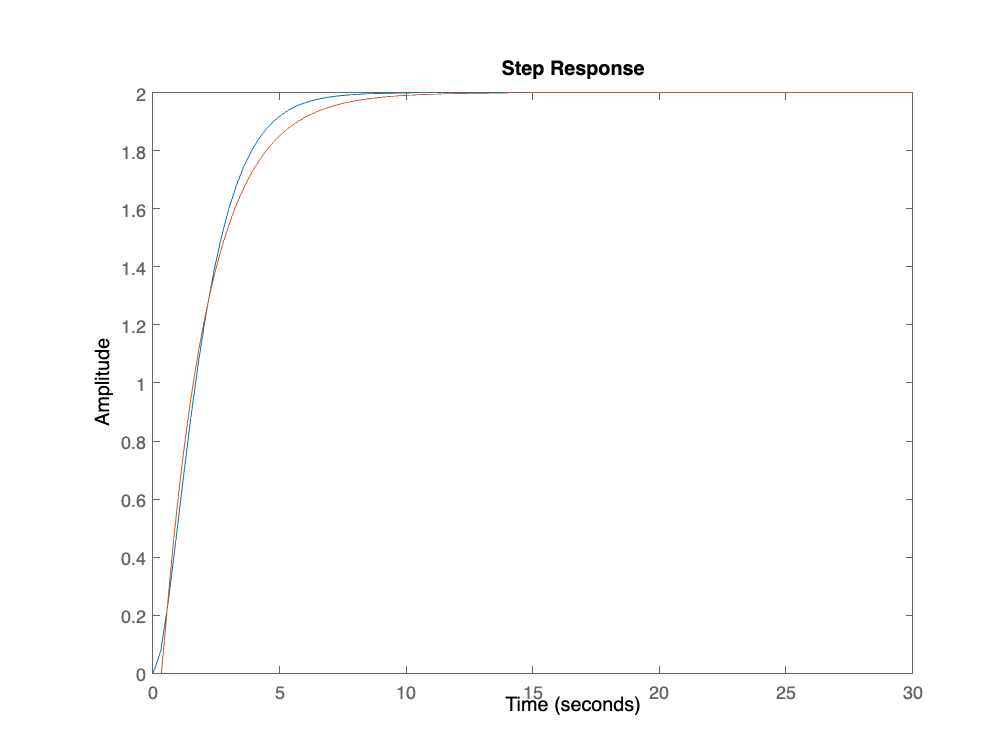

K = 2;
T = 0.35;
tau = 1.79;
M = tf(K, [tau 1], 'inputDelay', T);
step(H, 30) 
hold on;
step(M,30); hold off;

% Com 20% Overshoot

Kp = (0.6 * tau)/(K * T)

Kp = 1.5343

Ti = tau;
Td = T/2;

Ki = Kp/Ti

Ki = 0.8571

Kd = Kp*Td

Kd = 0.2685

result = sim("controle.slx");

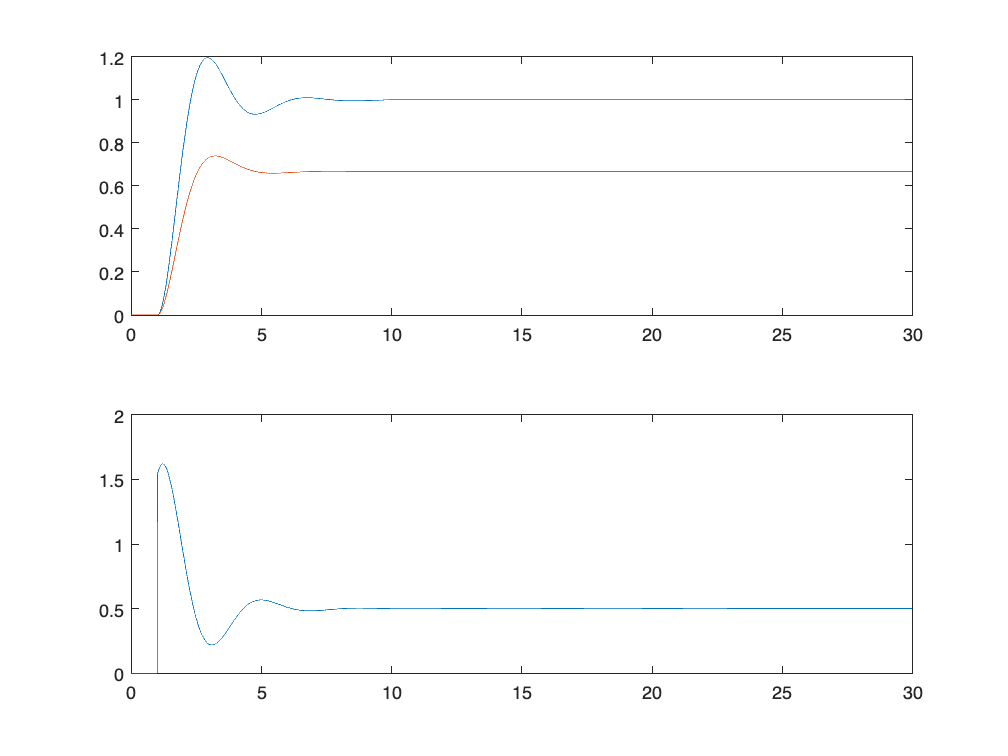

error = result.Error(:,2);
time = result.Error(:,1);
control = result.ControlAction(:,2);
output = result.Output(:,2);
model = result.Output(:,3);

figure(2)

subplot(211);
plot(time, output);
hold on;
plot(time, model);
hold on;

subplot(212);
plot(time, control);

step_time = 0.01;

IAE = 0;
ITAE = 0;

for i = 1:(20/step_time)
    error_abs_ist = abs(error(i));
    IAE = IAE + error_abs_ist;
    ITAE = ITAE + time(i) * error_abs_ist;
end

IAE = IAE * step_time

IAE = 1.0222

ITAE = ITAE * step_time

ITAE = 2.1974

max_value = max(output);
settling_value = output(end);

overshoot = max_value - settling_value

overshoot = 0.1954

v10 = settling_value * 0.1;
v90 = settling_value * 0.9;
output_bigger_v10 = find(output >= v10);
output_less_v90 = find(output <= v90);
t10 = time(output_bigger_v10(1));
t90 = time(output_less_v90(end));
RT = t90 - t10

RT = 0.8500

C = tf(Kd,1)+tf(Ki,[1 0])+tf([Kd 0],1)

C =
 
  0.2685 s^2 + 0.2685 s + 0.8571
  ------------------------------
                s
 
Continuous-time transfer function.



G = C * H

G =
 
  0.537 s^2 + 0.537 s + 1.714
  ---------------------------
        s^3 + 2 s^2 + s
 
Continuous-time transfer function.



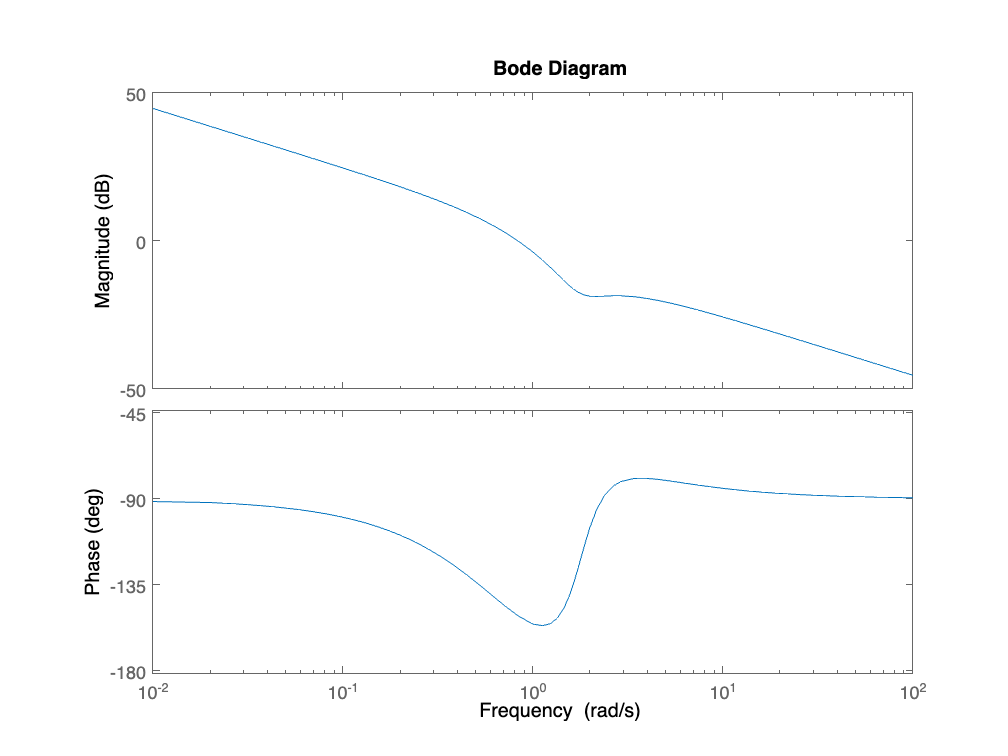

figure(3)
bode(G)

fc = 0.834

fc = 0.8340

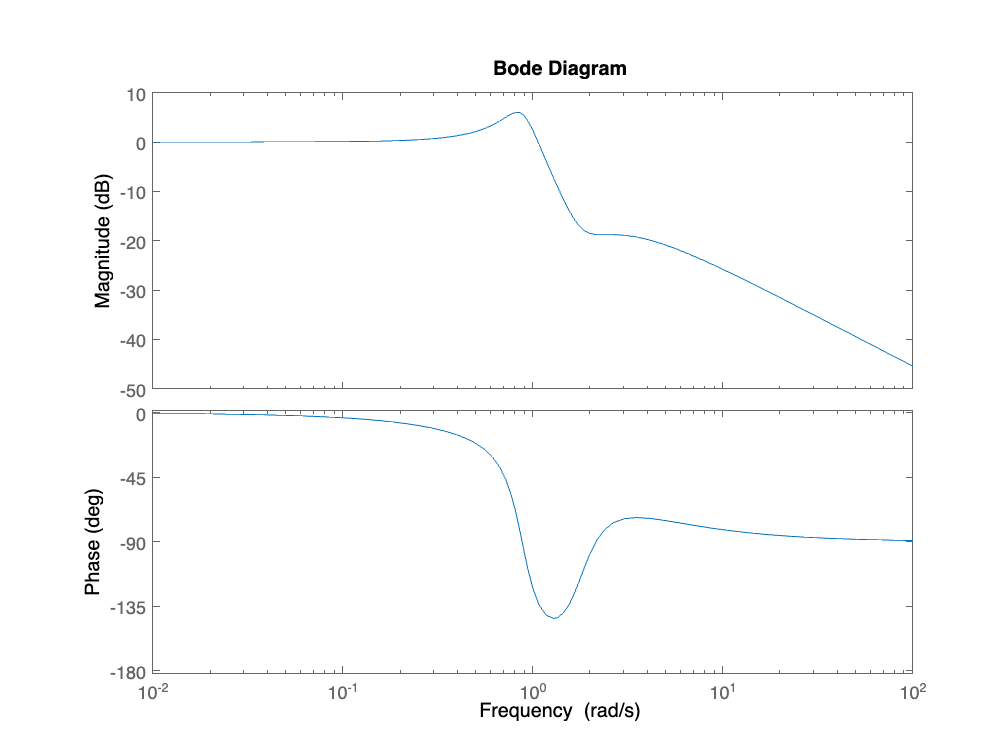

figure(4)
bode(feedback(G,1))

fbw = bandwidth(feedback(G,1))

fbw = 1.1509

wa = 500 * fbw

wa = 575.4443

delta_time = 2*pi/wa

delta_time = 0.0109

syms s sd z
Csym = (Kp + Ki/s + Kd*sd/(Kd*sd/20 + 1));
Csym = subs(Csym, s, (z-1)/step_time);
Csym = subs(Csym, sd, (z-1)/(z*step_time));
Csym = simplify(Csym)

$$Csym = \frac{3\,\left(1420723\,z^{2}-2768909\,z+1348586\right)}{350\,\left(937\,z^{2}-1474\,z+537\right)}$$

[Cnum, Cden] = numden(Csym);
C_discrete = tf(sym2poly(Cnum), sym2poly(Cden), delta_time)

C_discrete =
 
  4.262e06 z^2 - 8.307e06 z + 4.046e06
  ------------------------------------
     327950 z^2 - 515900 z + 187950
 
Sample time: 0.010919 seconds
Discrete-time transfer function.



H_discrete = c2d(H, delta_time)

H_discrete =
 
  0.0001184 z + 0.0001175
  -----------------------
  z^2 - 1.978 z + 0.9784
 
Sample time: 0.010919 seconds
Discrete-time transfer function.



[Hnum, Hden] = tfdata(H_discrete, 'v')

Hnum = 1.0e-03 *

         0    0.1184    0.1175


Hden =     1.0000   -1.9783    0.9784


result_discrete = sim("controle_discreto.slx");

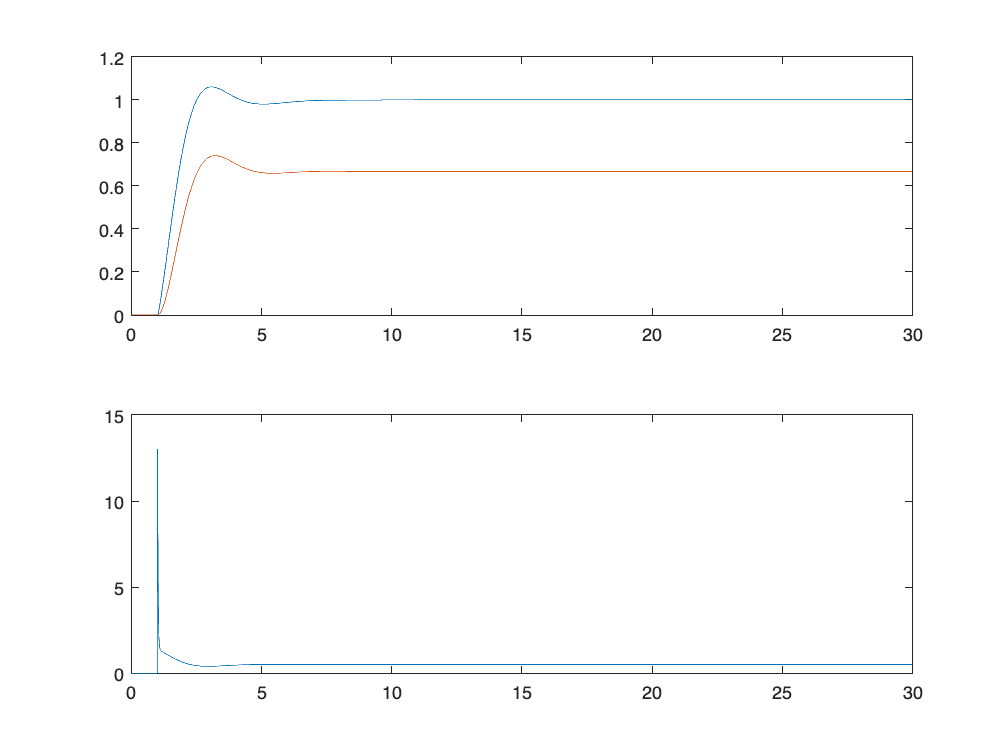

time_discrete = result_discrete.Error(:,1);
control_discrete = result_discrete.ControlAction(:,2);
output_discrete = result_discrete.Output(:,2);
model_discrete = result_discrete.Output(:,3);

figure(5)

subplot(211);
plot(time_discrete, output_discrete);
hold on;
plot(time_discrete, model_discrete);
hold on;

subplot(212);
plot(time_discrete, control_discrete);
hold off;

result_discrete_pc = sim("controle_discreto_pc.slx");

output_discrete_pc = result_discrete_pc.Output(:,2);
% time_discrete_pc = result_discrete_pc.Output(:,1);
% disturbance_discrete_pc = result_discrete_pc.Disturbance(:,2);
max_amplitude = max(output_discrete_pc) - output_discrete_pc(end)

max_amplitude = 0.4523

recovery_time = 14.6

recovery_time = 14.6000

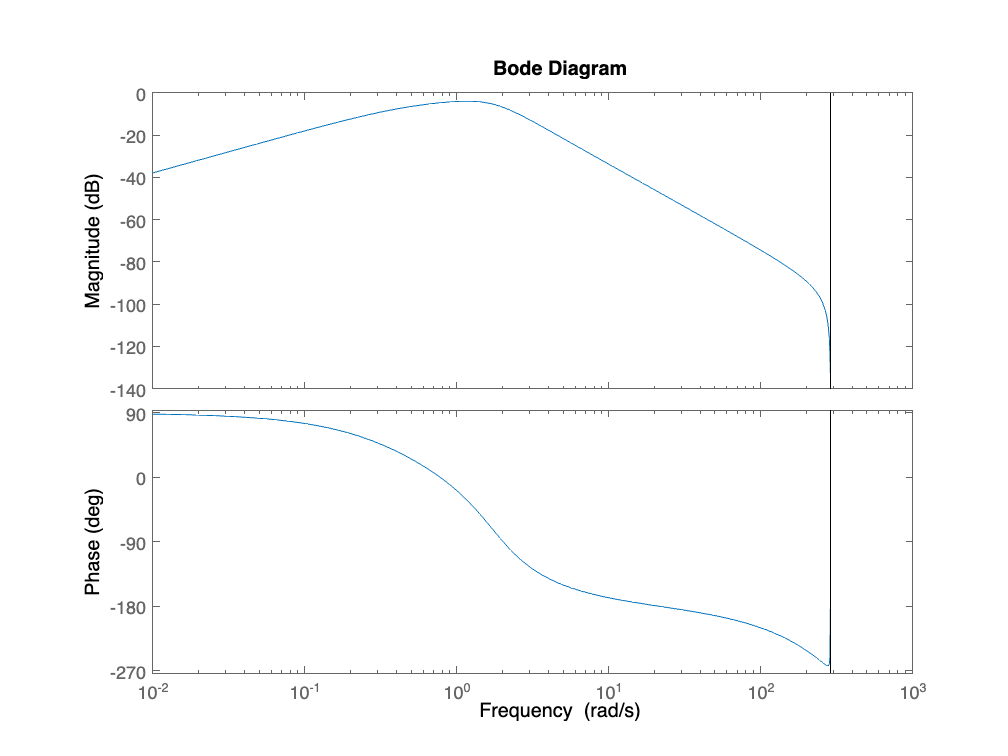


y_v = feedback(H_discrete, C_discrete);
figure(6)
bode(y_v)

load dados_ruido.mat
noise = timeseries(ruido);

result_discrete_pv = sim("controle_discreto_pv.slx");

control_discrete_pv = result_discrete_pv.ControlAction(:,2)

control_discrete_pv =    -0.5870
   -0.3586
   -0.2260
   -0.1489
   -0.1038
   -0.0773
   -0.0615
   -0.0519
   -0.0459
   -0.0420


noise_discrete_pv = result_discrete_pv.Disturbance{1}.Values.Data(1,:)'

noise_discrete_pv =     0.0452
    0.0446
    0.0441
    0.0436
    0.0430
    0.0425
    0.0420
    0.0414
    0.0409
    0.0404
